# Find SC


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv350eV_ke260_0003\Ada_PEPICO_hv350eV_ke260_0003_ana';
raw_data = IO.import_raw(dir);
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
Log: Background signal created for det2 on the signal(s) TOF,


## Event statistics from all data

e_R_range = [0; 19.0];
e_TRG.C1= macro.filter.write_coincidence_condition(1, 'det1'); % electron trigger
e_TRG.type	        = 'continuous';
e_TRG.data_pointer	= 'h.det1.R';
e_TRG.translate_condition = 'AND';
e_TRG.value		= e_R_range;

RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); % rnd trigger

[e_filter_et, ~]	= macro.filter.conditions_2_filter(data_converted,e_TRG);
data_stats.N_e = sum(e_filter_et);
[e_filter_rt, ~]	= macro.filter.conditions_2_filter(data_converted, RND_TRG);
data_stats.N_RND = sum(e_filter_rt);
%%% the scaling factor%%%
SC = data_stats.N_e / data_stats.N_RND;

[data_stats] =get_data_stats(data_converted);

The Scaling factor is 0.19895


% SC = data_stats.SC;
% TP_0 =data_stats.TP_0;

## Define etAI and rtAI

hit_filter_et = filter.events_2_hits(e_filter_et, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    e_TRG, data_converted);
et_tof= data_converted.h.det2.TOF(hit_filter_et.det2.filt); 

hit_filter_rt = filter.events_2_hits(e_filter_rt, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    RND_TRG, data_converted);
rt_tof= data_converted.h.det2.TOF(hit_filter_rt.det2.filt);


## make histogram

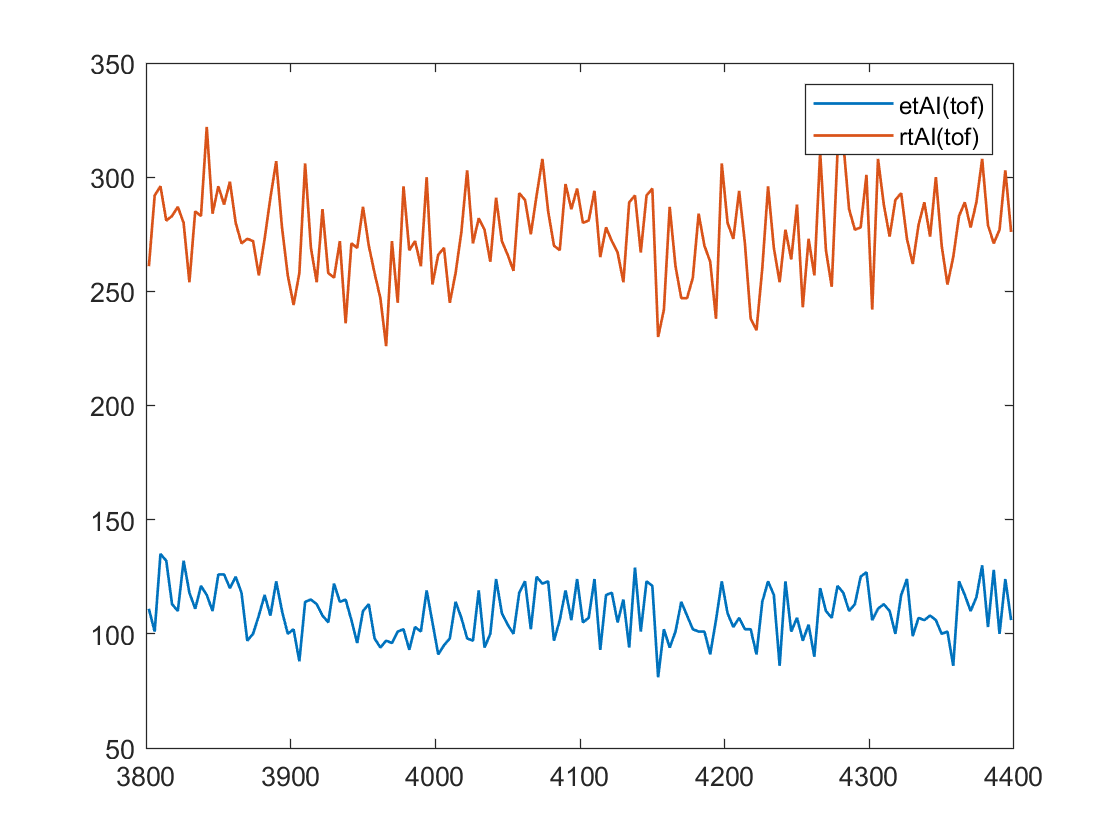

Binsize = 4; Binedges = 3800: Binsize: 4400;%0: Binsize: 11e3;
Bincenters = Binedges(1:end-1) + diff(Binedges) / 2;
et_tof_hist= histcounts(et_tof, Binedges);%,'Normalization','probability');
rt_tof_hist= histcounts(rt_tof, Binedges);%,'Normalization','probability');
figure
plot(Bincenters, et_tof_hist,'LineWidth',1,'DisplayName','etAI(tof)')
hold on
plot(Bincenters, rt_tof_hist,'LineWidth',1,'DisplayName','rtAI(tof)' )
legend

## Estimate SC

SC_v = et_tof_hist./rt_tof_hist;
SC = mean(SC_v);

## Filter Ion TOF

% SC=1;
Tet_tof = et_tof_hist - SC.* rt_tof_hist;
Tet_tof_error = sqrt(et_tof_hist + (SC.^2).* rt_tof_hist)

Tet_tof_error =    12.3380   12.1295   13.4817   13.2811   12.5580   12.4633   13.2751   12.5746   12.4907   12.8725   12.9562   12.4443   13.1437   13.0955   12.9256   13.0088   12.6810   11.8373   11.9568   12.1900   12.6540   12.4083   13.0955   12.4061   11.8573   11.8550   11.3470   12.7411   12.5495   12.3742   12.3764   12.0728   12.7451   12.5286   12.3401   12.1986   11.7682   12.4633   12.4759   11.7794   11.5332   11.5195   11.7883   11.8195   12.1965   11.6333   12.0816   11.9259   12.8991   12.0401


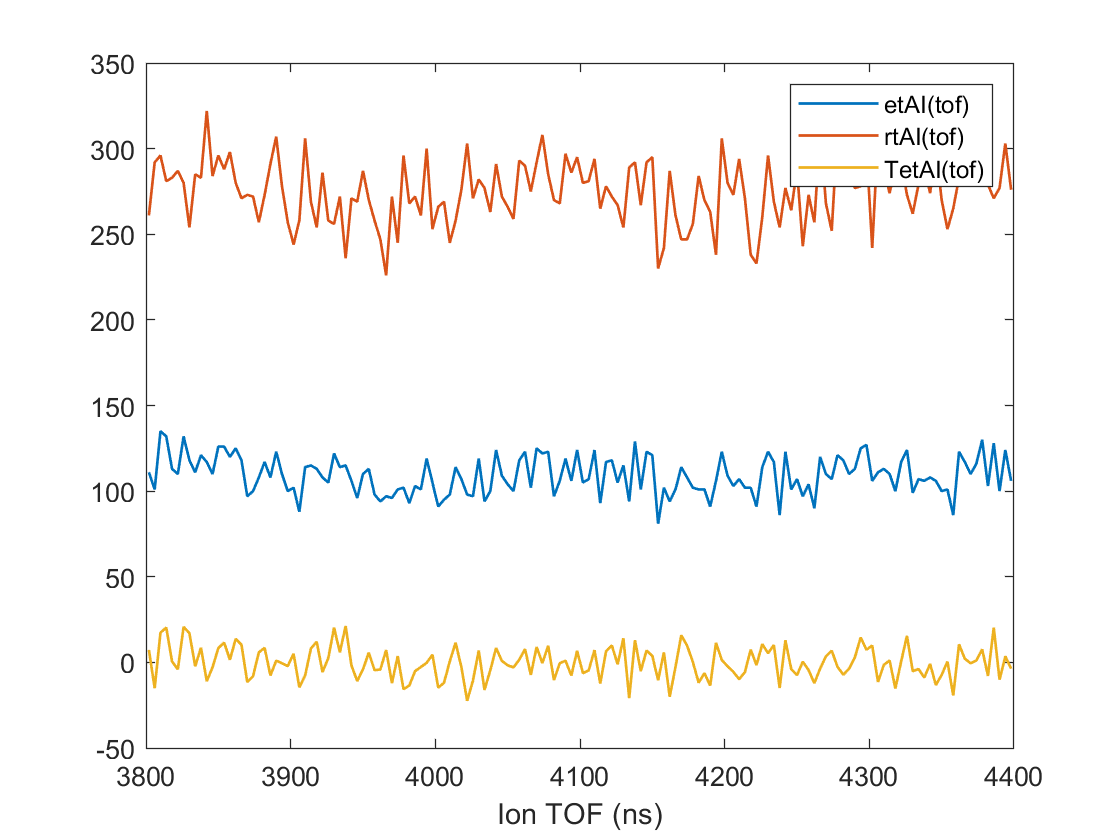

plot(Bincenters, Tet_tof ,'LineWidth',1,'DisplayName','TetAI(tof)')
xlabel('Ion TOF (ns)')

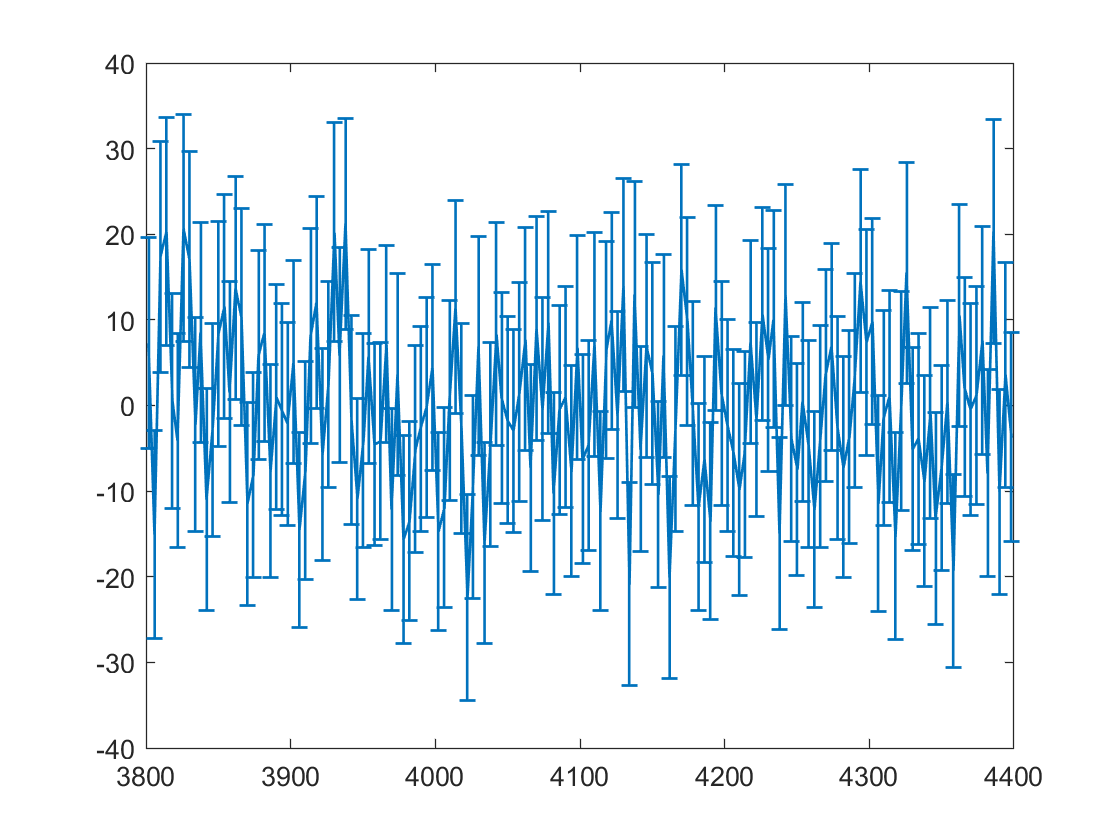


figure
errorbar(Bincenters,Tet_tof ,Tet_tof_error, 'LineWidth',1,'DisplayName','TetAI(tof)')

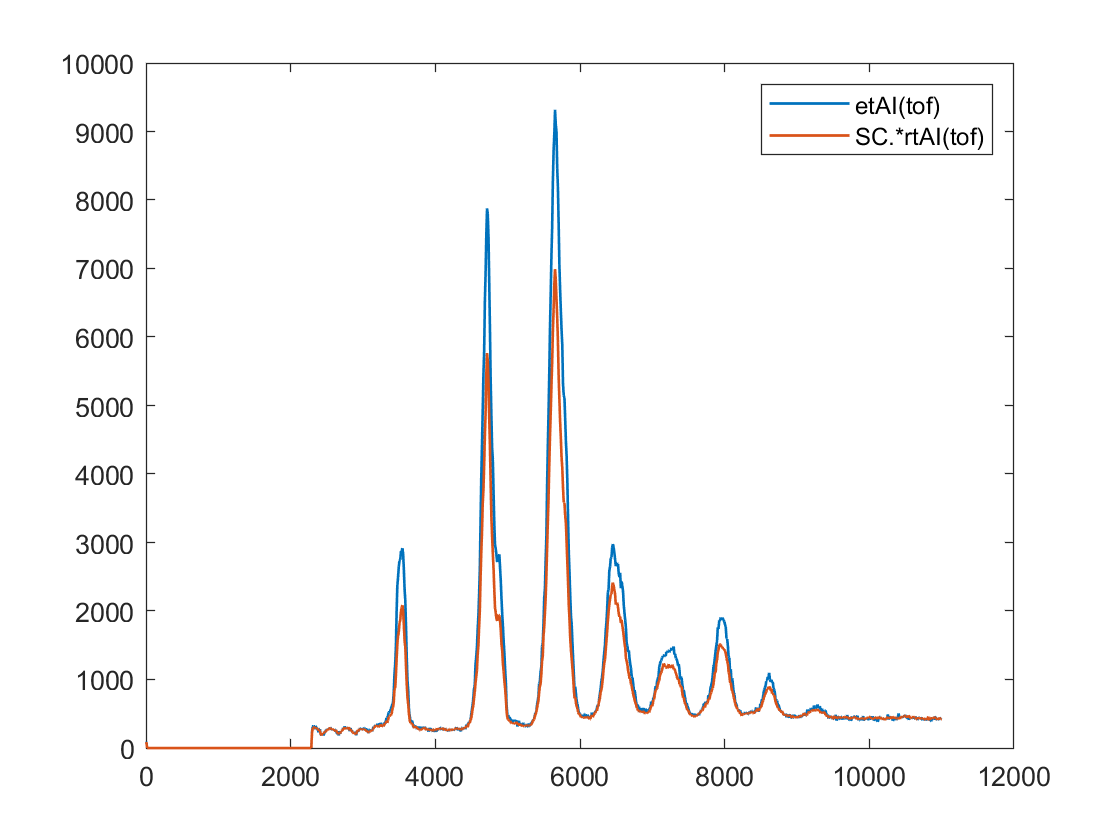

%% make histogram

Binsize = 10; Binedges = 0: Binsize: 11e3;
Bincenters = Binedges(1:end-1) + diff(Binedges) / 2;
et_tof_hist= histcounts(et_tof, Binedges);%,'Normalization','probability');
rt_tof_hist= histcounts(rt_tof, Binedges);%,'Normalization','probability');
figure
plot(Bincenters, et_tof_hist,'LineWidth',1,'DisplayName','etAI(tof)')
hold on
plot(Bincenters, SC.*rt_tof_hist,'LineWidth',1,'DisplayName','SC.*rtAI(tof)' )
legend

## Filter Ion TOF

% SC=1;
figure
Tet_tof = et_tof_hist - SC.* rt_tof_hist;
% Tet_tof = max(Tet_tof,0);
Tet_tof_error = sqrt(et_tof_hist + (SC.^2).* rt_tof_hist)

Tet_tof_error =    11.3978         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


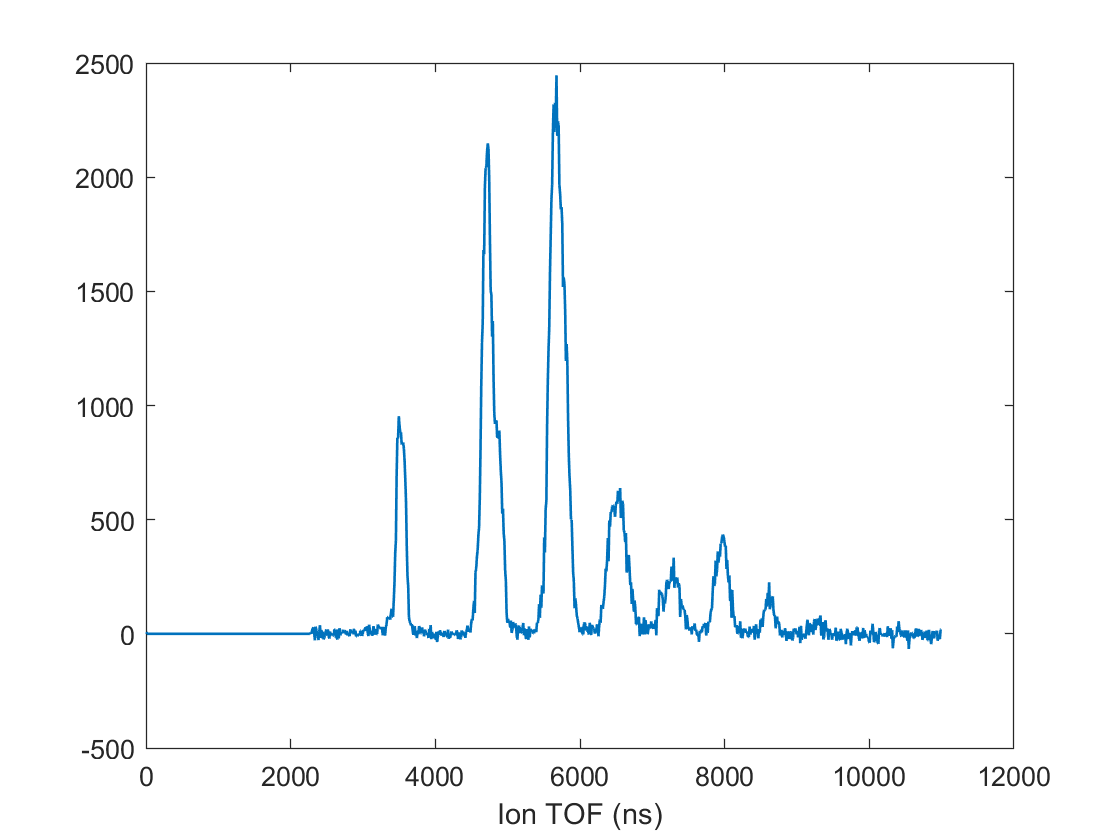

plot(Bincenters, Tet_tof ,'LineWidth',1,'DisplayName','TetAI(tof)')
xlabel('Ion TOF (ns)')

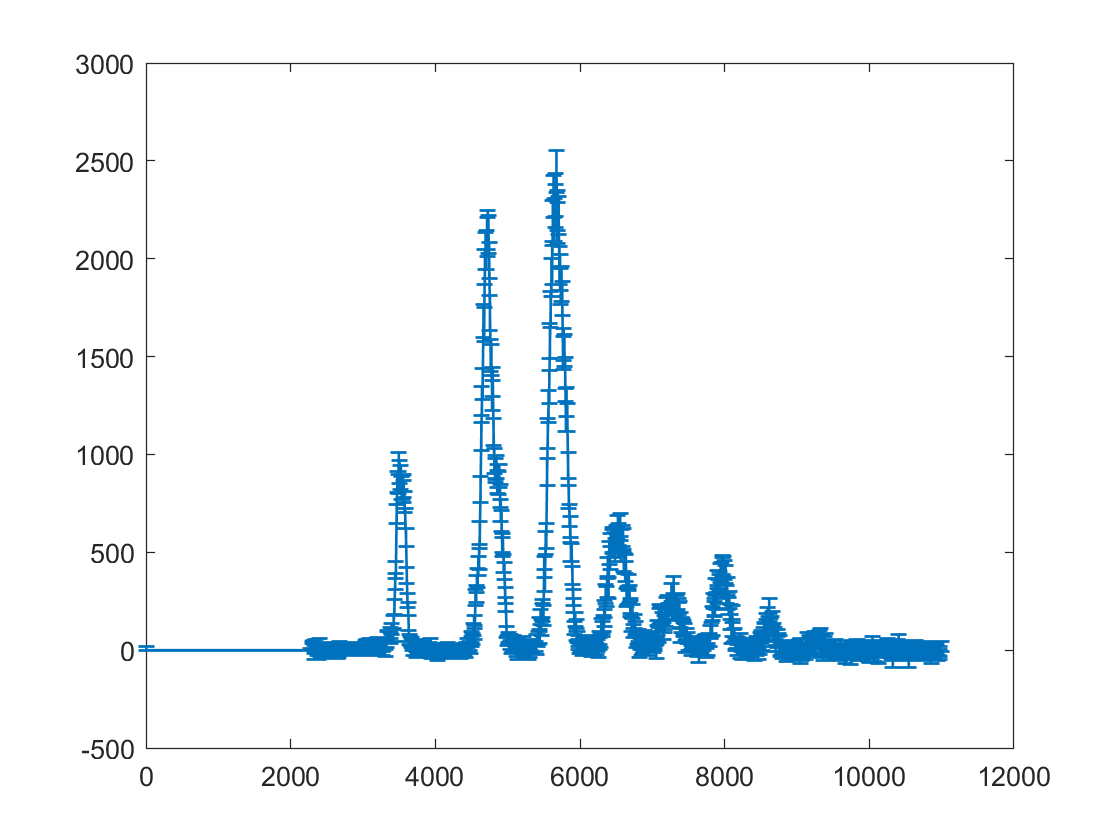


figure
errorbar(Bincenters,Tet_tof ,Tet_tof_error, 'LineWidth',1,'DisplayName','TetAI(tof)')